# GPX History Analysis

**Author: CARLOS M N**

**DNI: XXXXXXXX-X**

Clear workspace

clear all; clc; close all;

General variables

data_path = './data/';

# Geohits data analysis

## Load GPX data for the analysis

gpx_data = readtable(strcat(data_path,'gpx_info_processed.csv'))

gpx_data = 3414951×5 table
        ID        dt     latitude    longitude    elevation
    __________    ___    ________    _________    _________

    1.0366e+09      0     40.589      -4.9664      1132.2  
    1.0366e+09     39     40.589      -4.9664        1132  
    1.0366e+09     53     40.589      -4.9664      1132.1  
    1.0366e+09     55     40.589      -4.9664      1132.1  
    1.0366e+09     58     40.589      -4.9664      1132.1  
    1.0366e+09     61     40.589      -4.9663      1132.1  
    1.0366e+09    101     40.589      -4.9664      1132.1  
    1.0366e+09    103     40.589      -4.9664      1132.1  
    1.0366e+09    105     40.589      -4.9664      1132.1  
    1.0366e+09    107     40.589      -4.9664      1132.1  
    1.0366e+09    108     40.589      -4.9664        1132  
    1.0366e+09    109 

position_tbl = gpx_data(:,["latitude", "longitude"])

position_tbl = 3414951×2 table
    latitude    longitude
    ________    _________

     40.589      -4.9664 
     40.589      -4.9664 
     40.589      -4.9664 
     40.589      -4.9664 
     40.589      -4.9664 
     40.589      -4.9663 
     40.589      -4.9664 
     40.589      -4.9664 
     40.589      -4.9664 
     40.589      -4.9664 
     40.589      -4.9664 
     40.589      -4.9663 
     40.589      -4.9663 
     40.589      -4.9663 
     40.589      -4.9663 
     40.589      -4.9663 


min(position_tbl.latitude)

ans = 40.2085

max(position_tbl.latitude)

ans = 51.5368

min(position_tbl.longitude)

ans = -9.2110

max(position_tbl.longitude)

ans = 12.2329

min(gpx_data.elevation)

ans = -1.7000

max(gpx_data.elevation)

ans = 2.8523e+03

## Try clustering methods

### Hierarchical clustering

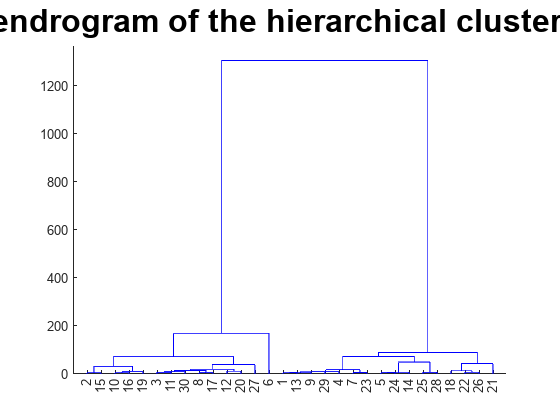


% Downsample data using random sampling ( memory issues)
sample_size = 0.005; % Sample 0.5% of the data
idx = randsample(height(position_tbl), round(height(position_tbl) * sample_size));
position_array = table2array(position_tbl(idx,:));

% Compute pairwise distance using the 'great_circle_distance' distance measure
% D = pdist(position_array, @great_circle_distance);
D = pdist(position_array, "euclidean");

% Perform hierarchical clustering
Z = linkage(D, "ward");

% Plot the dendrogram
figure
dendrogram(Z);
title('Dendrogram of the hierarchical clustering', FontSize=24)
saveas(gcf,strcat('Figures/hier_dendrogram.png') )
hold off

#### Get centroids and borders

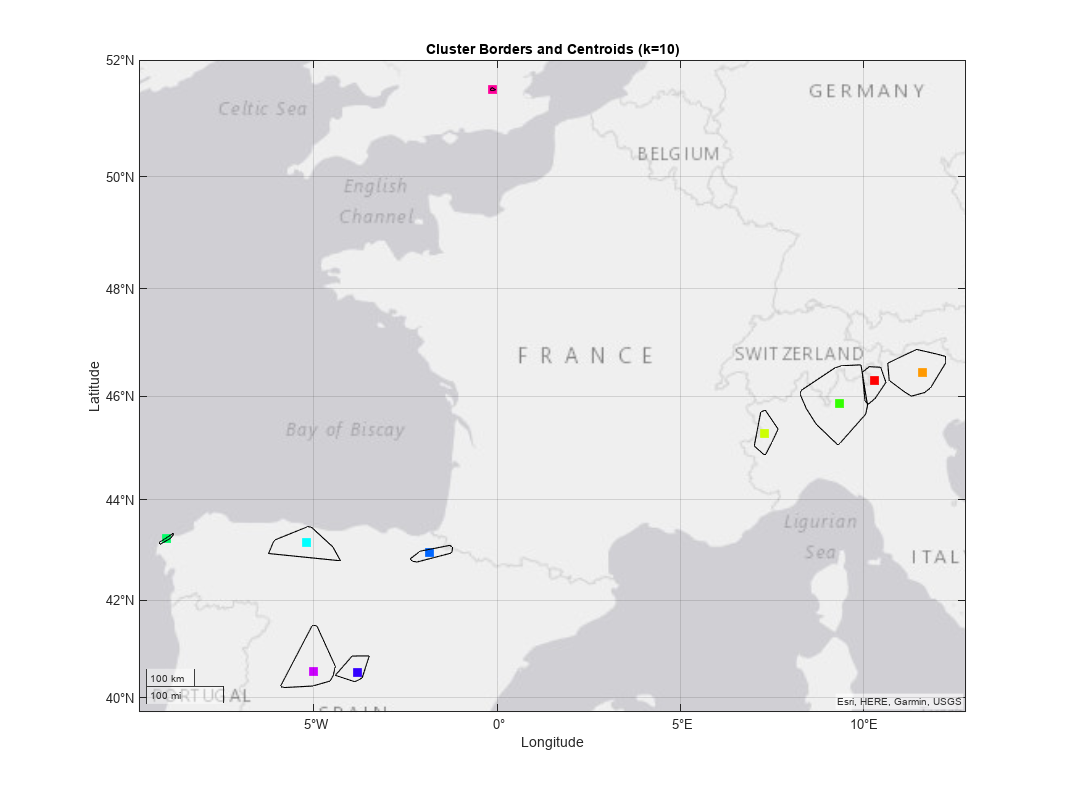

% Assign points to clusters using the 'cutree' method
for k = 2:10 % Number of clusters
    T = cluster(Z, 'maxclust', k);
    
    % Loop over clusters
    centroids = zeros(k, size(position_array,2)); % Initialize centroids array
    borders = cell(k,1); % Initialize borders cell array
    for i = 1:k
        % Extract points in cluster i
        points = position_array(T==i,:);
    
        % Compute centroid of cluster i
        centroids(i,:) = mean(points,1);
        
        % Compute convex hull of cluster i
        K = convhull(points(:,1), points(:,2));
        
        % Store convex hull in borders cell array
        borders{i} = points(K,:);
    end
    
    %% Plot the clusters
    
    % Set color map
    colors = hsv(k); % Default Matlab color map
    
    % Plot the centroids of the clusters
    i = 1;
    geoscatter(centroids(i,1),centroids(i,2),'MarkerEdgeColor', colors(i,:), 'MarkerFaceColor', colors(i,:), 'LineWidth', 2, 'Marker', 'square');
    hold on
    for i = 2:k
        geoscatter(centroids(i,1),centroids(i,2),'MarkerEdgeColor', colors(i,:), 'MarkerFaceColor', colors(i,:), 'LineWidth', 2, 'Marker', 'square');
    end
    
    % Plot the borders of the clusters
    for i = 1:k
        % Extract points in cluster i
        points = borders{i};
        
        % Plot the convex hull of cluster i with transparent fill
        geoplot(points(:,1), points(:,2), 'k');
    end
    
    % Configure plot
    hold off
    % axis equal
    % xlabel('Longitude');
    % ylabel('Latitude');
    title(strcat('Cluster Borders and Centroids (k=',num2str(k),')'), FontSize=24);
    set(gcf, 'Position', [0 0 1200 900])
    % legend(Location='eastoutside')
    saveas(gcf,strcat('Figures/hier_clusters_k',num2str(k),'.png') )
end

### Kmeans

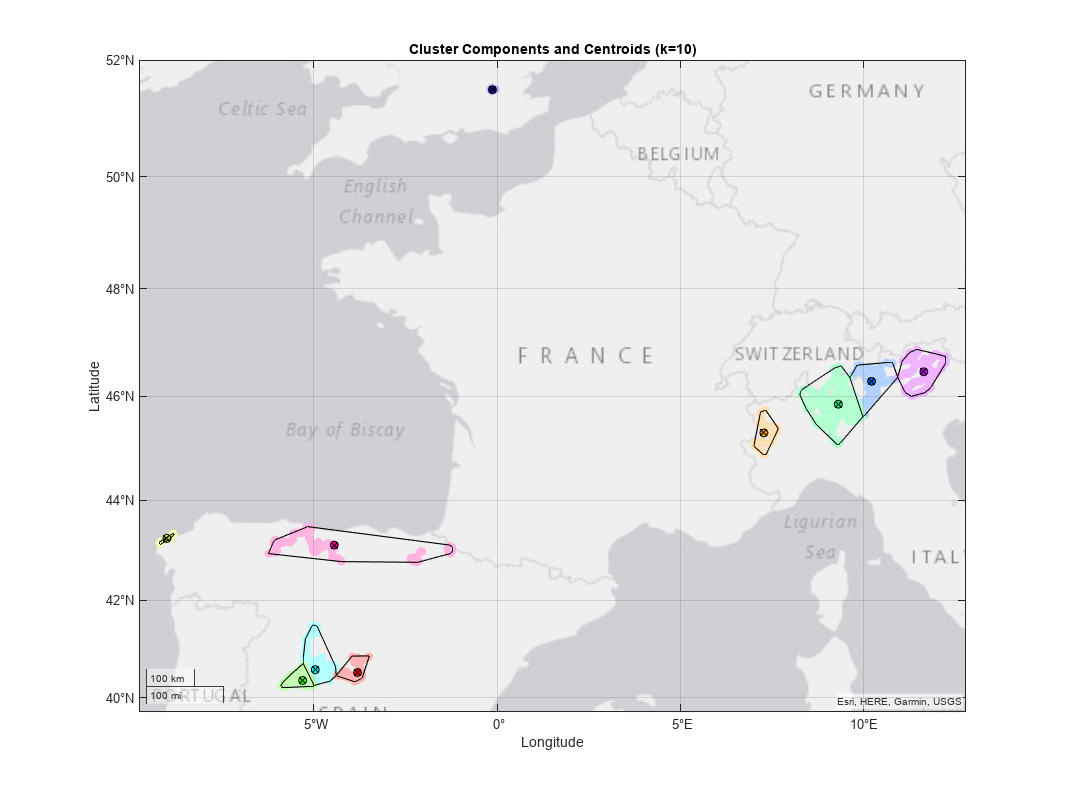

% Compute k-means clustering for different values of k
k_values = 2:10;
errors = zeros(size(k_values));
for ii = 1:length(k_values)
    k = k_values(ii);
    [idx, C, sumd] = kmeans(table2array(position_tbl), k);
    errors(ii) = sum(sumd);

    borders = cell(k,1); % Initialize borders cell array
    for i = 1:k
        % Extract points in cluster i
        points = table2array(position_tbl(idx==i,:));
        
        % Compute convex hull of cluster i
        K = convhull(points(:,1), points(:,2));
        
        % Store convex hull in borders cell array
        borders{i} = points(K,:);
    end
    
    %
    colors = hsv(k); % Default Matlab color map
    geoscatter(position_tbl(idx==1,:),'latitude','longitude','filled','MarkerFaceColor',1-colors(1,:)*0.3)
    hold on
    for jj = 2:k
        geoscatter(position_tbl(idx==jj,:),'latitude','longitude','filled','MarkerFaceColor',1-colors(jj,:)*0.3)
    end
    for jj = 1:k
        geoscatter(C(jj,1),C(jj,2),'filled','MarkerFaceColor',1-colors(jj,:),'MarkerEdgeColor','k', 'Marker','o')
        geoscatter(C(jj,1),C(jj,2),'filled','MarkerEdgeColor','k', 'Marker','x')
    end
    % Plot the borders of the clusters
    for i = 1:k
        % Extract points in cluster i
        points = borders{i};
        
        % Plot the convex hull of cluster i with transparent fill
        geoplot(points(:,1), points(:,2), 'k');
    end
    hold off
    title(strcat('Cluster Components and Centroids (k=',num2str(k),')'), FontSize=24);
    set(gcf, 'Position', [0 0 1200 900])
    % legend(Location='eastoutside')
    saveas(gcf,strcat('Figures/kmeans_clusters_k',num2str(k),'.png') )
end

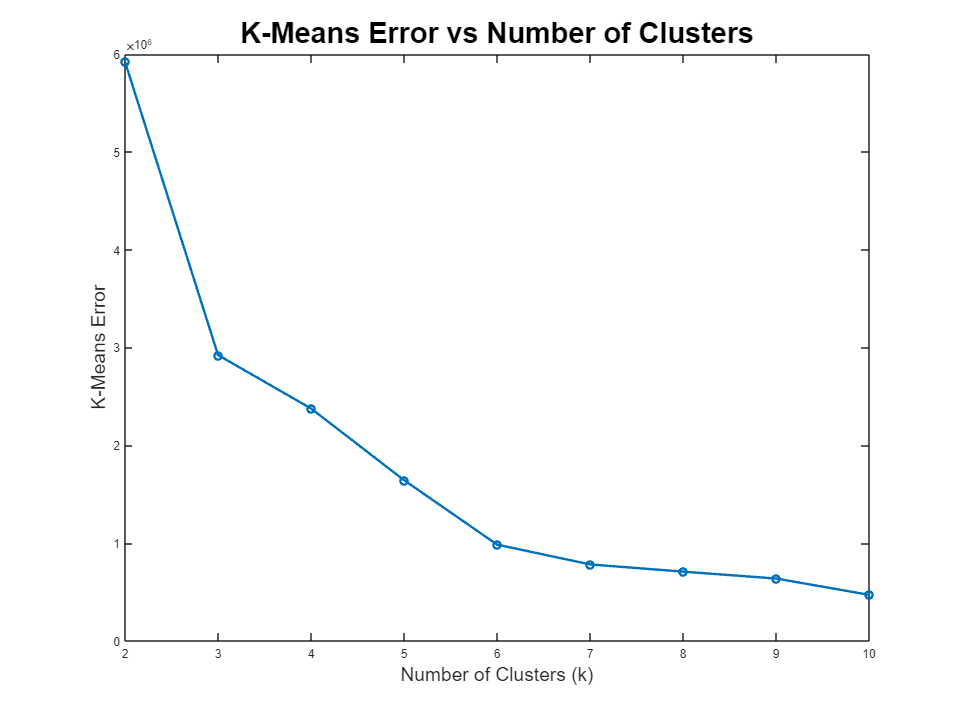


% Plot the results
plot(k_values, errors, '-o', 'LineWidth', 2);

% Configure plot
xlabel('Number of Clusters (k)', FontSize=16);
ylabel('K-Means Error', FontSize=16);
title('K-Means Error vs Number of Clusters', FontSize=24);
saveas(gcf,strcat('Figures/kmeans_errors.png') )

## Focus on start/end points

% Get starting points (dt==0)
idx_s = gpx_data.dt==0;
% As activities are concatenated, before every start point the table stores
% the end point of previous activity
idx_end = circshift(idx_s,-1);
% Combine both indexes
idx = idx_s | idx_end;

position_array = table2array(position_tbl(idx,:));

### Hierarchical clustering

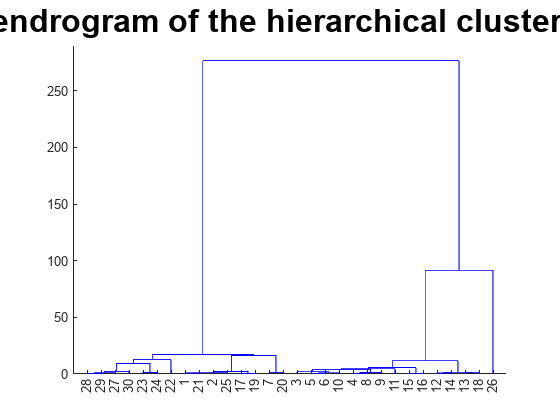

% Compute pairwise distance using the 'great_circle_distance' distance measure
% D = pdist(position_array, @great_circle_distance);
D = pdist(position_array, "euclidean");

% Perform hierarchical clustering
Z = linkage(D, "ward");

% Plot the dendrogram
figure
dendrogram(Z);
title('Dendrogram of the hierarchical clustering', FontSize=24)
saveas(gcf,strcat('Figures/hier_dendrogram_startend.png') )

#### Get centroids and borders

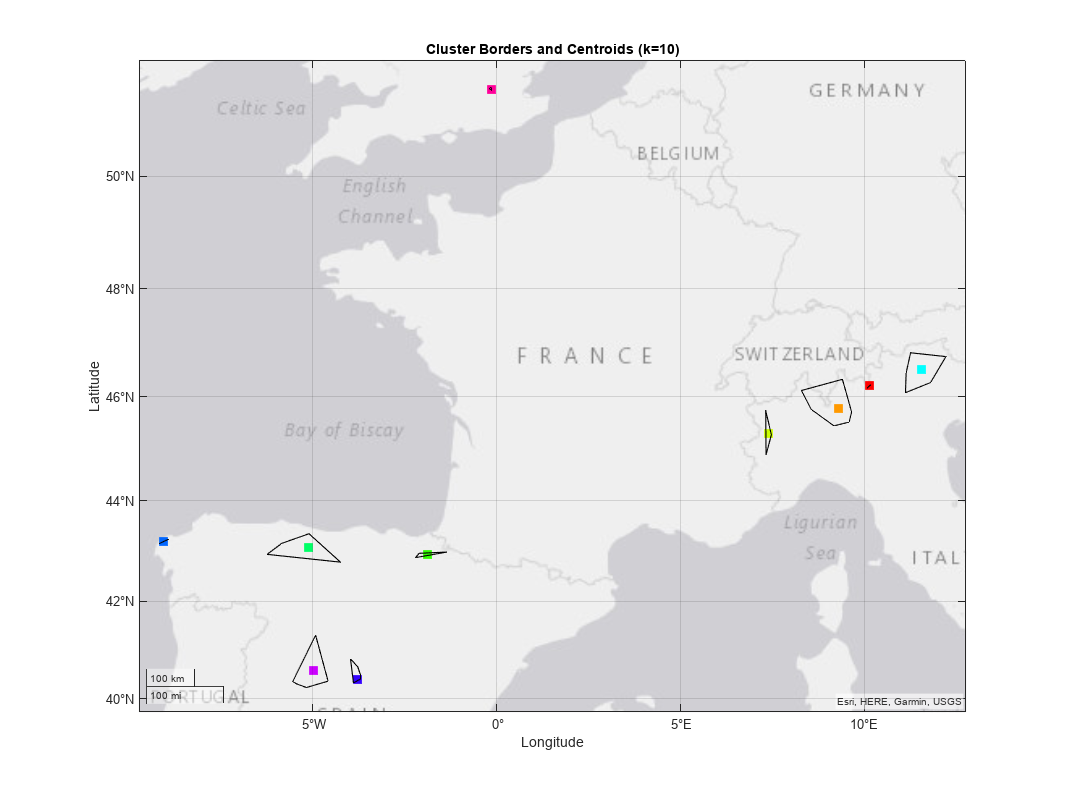

% Assign points to clusters using the 'cutree' method
for k = 2:10 % Number of clusters
    T = cluster(Z, 'maxclust', k);
    
    % Loop over clusters
    centroids = zeros(k, size(position_array,2)); % Initialize centroids array
    borders = cell(k,1); % Initialize borders cell array
    for i = 1:k
        % Extract points in cluster i
        points = position_array(T==i,:);
    
        % Compute centroid of cluster i
        centroids(i,:) = mean(points,1);
        
        % Compute convex hull of cluster i
        K = convhull(points(:,1), points(:,2));
        
        % Store convex hull in borders cell array
        borders{i} = points(K,:);
    end
    
    %% Plot the clusters
    
    % Set color map
    colors = hsv(k); % Default Matlab color map
    
    % Plot the centroids of the clusters
    i = 1;
    geoscatter(centroids(i,1),centroids(i,2),'MarkerEdgeColor', colors(i,:), 'MarkerFaceColor', colors(i,:), 'LineWidth', 2, 'Marker', 'square');
    hold on
    for i = 2:k
        geoscatter(centroids(i,1),centroids(i,2),'MarkerEdgeColor', colors(i,:), 'MarkerFaceColor', colors(i,:), 'LineWidth', 2, 'Marker', 'square');
    end
    
    % Plot the borders of the clusters
    for i = 1:k
        % Extract points in cluster i
        points = borders{i};
        
        % Plot the convex hull of cluster i with transparent fill
        geoplot(points(:,1), points(:,2), 'k');
    end
    
    % Configure plot
    hold off
    % axis equal
    % xlabel('Longitude');
    % ylabel('Latitude');
    title(strcat('Cluster Borders and Centroids (k=',num2str(k),')'), FontSize=24);
    set(gcf, 'Position', [0 0 1200 900])
    % legend(Location='eastoutside')
    saveas(gcf,strcat('Figures/hier_clusters_startend_k',num2str(k),'.png') )
end

#### Kmeans

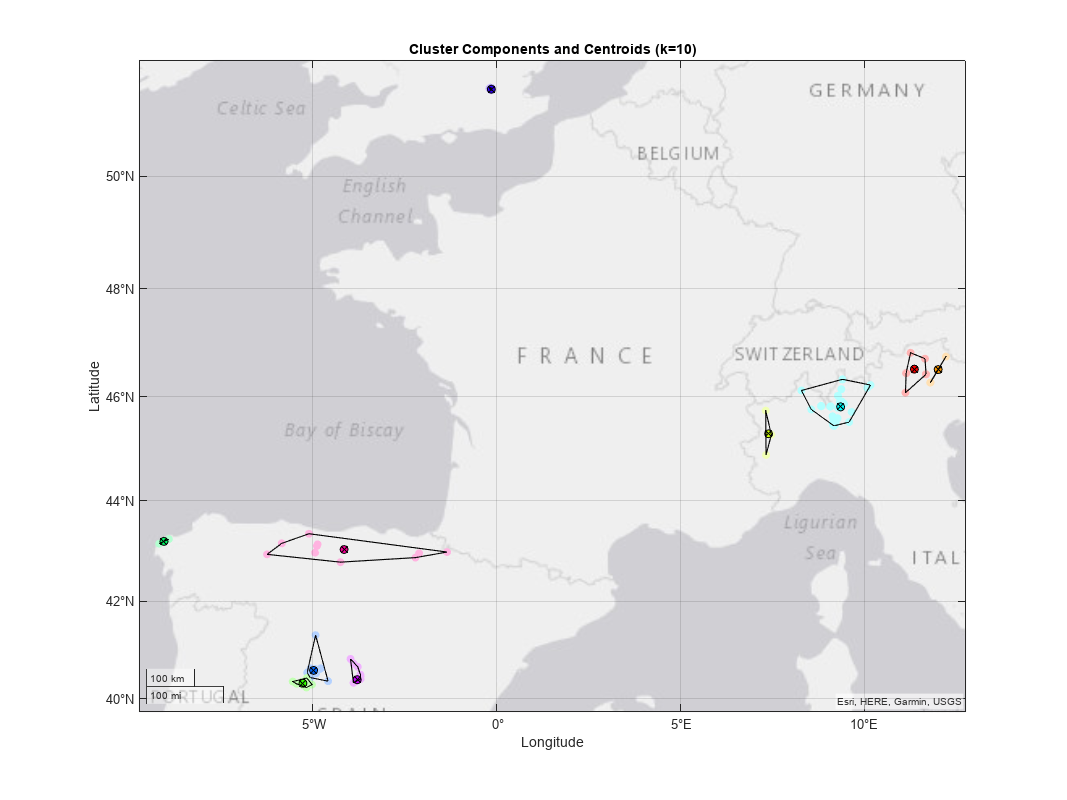

% Compute k-means clustering for different values of k
k_values = 2:10;
errors = zeros(size(k_values));
for ii = 1:length(k_values)
    k = k_values(ii);
    [idx, C, sumd] = kmeans(position_array, k);
    errors(ii) = sum(sumd);
    
    borders = cell(k,1); % Initialize borders cell array
    for i = 1:k
        % Extract points in cluster i
        points = position_array(idx==i,:);
        
        % Compute convex hull of cluster i
        K = convhull(points(:,1), points(:,2));
        
        % Store convex hull in borders cell array
        borders{i} = points(K,:);
    end
    %
    colors = hsv(k); % Default Matlab color map
    geoscatter(position_array(idx==1,1),position_array(idx==1,2),'filled','MarkerFaceColor',1-colors(1,:)*0.3)
    hold on
    for jj = 2:k
        geoscatter(position_array(idx==jj,1),position_array(idx==jj,2),'filled','MarkerFaceColor',1-colors(jj,:)*0.3)
    end
    for jj = 1:k
        geoscatter(C(jj,1),C(jj,2),'filled','MarkerFaceColor',1-colors(jj,:),'MarkerEdgeColor','k', 'Marker','o')
        geoscatter(C(jj,1),C(jj,2),'filled','MarkerEdgeColor','k', 'Marker','x')
    end
    % Plot the borders of the clusters
    for i = 1:k
        % Extract points in cluster i
        points = borders{i};
        
        % Plot the convex hull of cluster i with transparent fill
        geoplot(points(:,1), points(:,2), 'k');
    end
    hold off
    title(strcat('Cluster Components and Centroids (k=',num2str(k),')'), FontSize=24);
    set(gcf, 'Position', [0 0 1200 900])
    % legend(Location='eastoutside')
    saveas(gcf,strcat('Figures/kmeans_clusters_startend_k',num2str(k),'.png') )
end

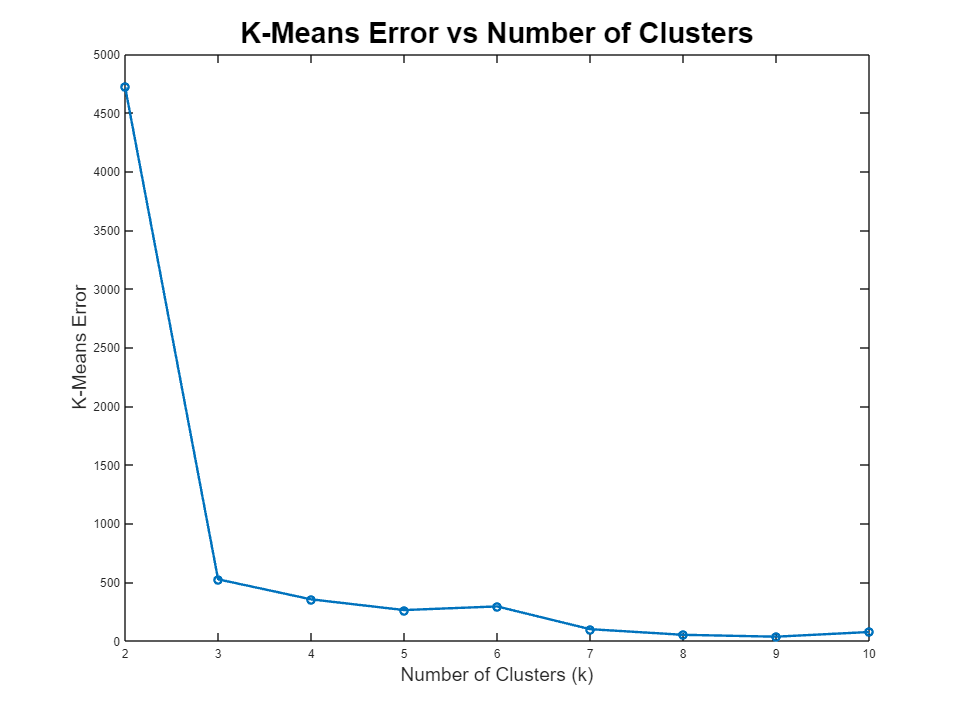


% Plot the results
plot(k_values, errors, '-o', 'LineWidth', 2);

% Configure plot
xlabel('Number of Clusters (k)', FontSize=16);
ylabel('K-Means Error', FontSize=16);
title('K-Means Error vs Number of Clusters', FontSize=24);
saveas(gcf,strcat('Figures/kmeans_errors_startend.png') )

# Privacy issues: frequent routes and home location

Focus on Italy activities for not revealing current home location

italy_gpx = gpx_data(gpx_data.longitude > 5,:);
italy_position = table2array(italy_gpx(:,["latitude", "longitude"]));

% Get starting points (dt==0)
idx_s = italy_gpx.dt==0;
% As activities are concatenated, before every start point the table stores
% the end point of previous activity
idx_end = circshift(idx_s,-1);
% Combine both indexes
idx = idx_s | idx_end;
italy_startend = italy_position(idx,:);

#### Plot those geopoints

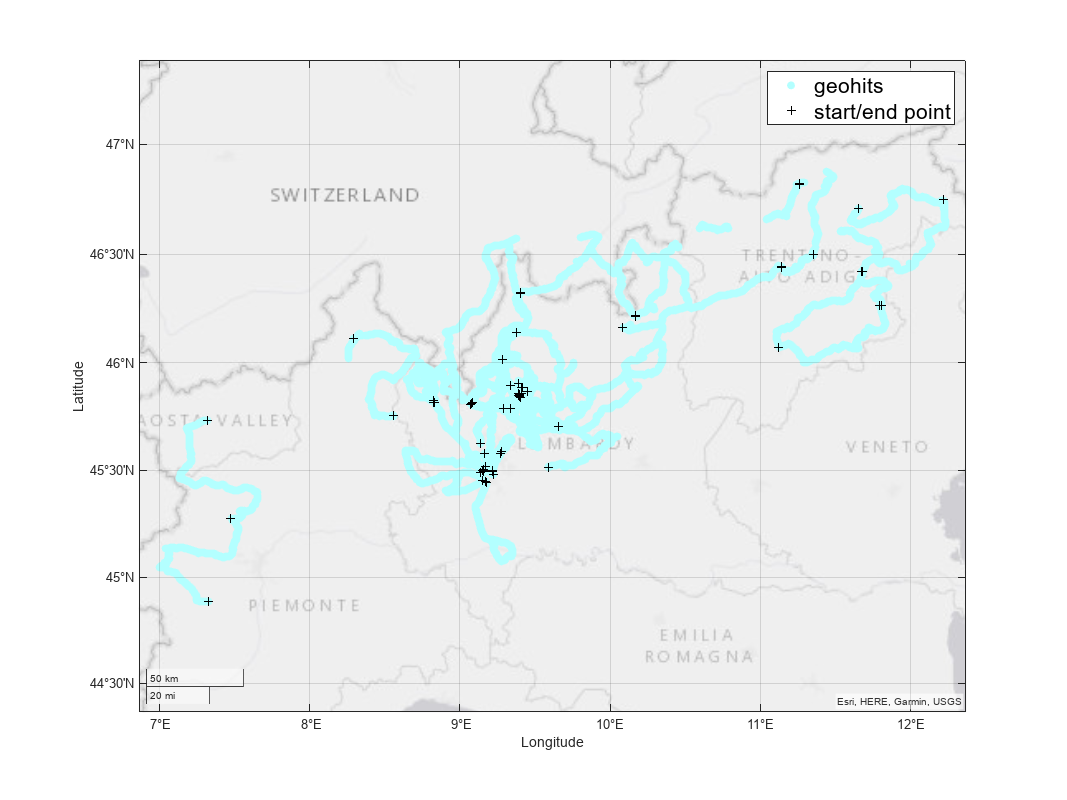

colors = hsv(1);
% Plot points over OSM map
% webmap('OpenStreetMap')
geoscatter(italy_position(:,1), italy_position(:,2),'filled','MarkerFaceColor',1-colors(1,:)*0.3)
hold on
geoscatter(italy_startend(:,1), italy_startend(:,2),'Marker','+','MarkerEdgeColor','k')
hold off
legend('geohits','start/end point', FontSize=16)
set(gcf, 'Position', [0 0 1200 900])
saveas(gcf,strcat('Figures/geohits_italy.png') )

#### Artificially increase influence of start end points (repeating them N times)

N = 1000;
positions_to_cluster = cat(1, italy_position, repmat(italy_startend, N, 1));

### Clustering with Kmeans

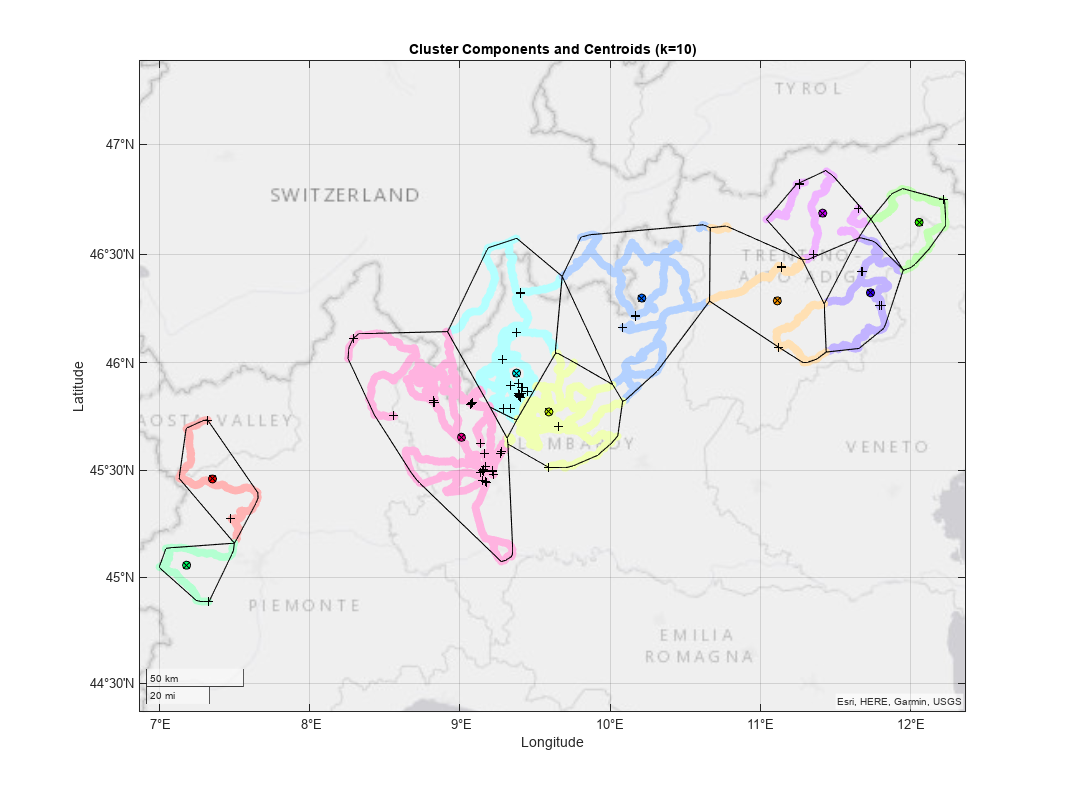

% Compute k-means clustering for different values of k
k_values = 2:10;
errors = zeros(size(k_values));
startend_cluster = zeros(size(k_values,1),size(italy_startend,1));
for ii = 1:length(k_values)
    k = k_values(ii);
    [idx, C, sumd] = kmeans(positions_to_cluster, k);
    errors(ii) = sum(sumd);
    
    borders = cell(k,1); % Initialize borders cell array
    for i = 1:k
        % Extract points in cluster i
        points = positions_to_cluster(idx==i,:);
        
        % Compute convex hull of cluster i
        K = convhull(points(:,1), points(:,2));
        
        % Store convex hull in borders cell array
        borders{i} = points(K,:);
    end

    startend_cluster(ii,:) = idx(size(italy_position,1)+1:size(italy_position,1)+size(italy_startend,1),:);
    %
    colors = hsv(k); % Default Matlab color map
    geoscatter(positions_to_cluster(idx==1,1),positions_to_cluster(idx==1,2),'filled','MarkerFaceColor',1-colors(1,:)*0.3)
    hold on
    for jj = 2:k
        geoscatter(positions_to_cluster(idx==jj,1),positions_to_cluster(idx==jj,2),'filled','MarkerFaceColor',1-colors(jj,:)*0.3)
    end
    for jj = 1:k
        geoscatter(C(jj,1),C(jj,2),'filled','MarkerFaceColor',1-colors(jj,:),'MarkerEdgeColor','k', 'Marker','o')
        geoscatter(C(jj,1),C(jj,2),'filled','MarkerEdgeColor','k', 'Marker','x')
    end
    geoscatter(italy_startend(:,1), italy_startend(:,2),'Marker','+','MarkerEdgeColor','k')
    % Plot the borders of the clusters
    for i = 1:k
        % Extract points in cluster i
        points = borders{i};
        
        % Plot the convex hull of cluster i with transparent fill
        geoplot(points(:,1), points(:,2), 'k');
    end
    hold off
    title(strcat('Cluster Components and Centroids (k=',num2str(k),')'), FontSize=24);
    set(gcf, 'Position', [0 0 1200 900])
    % legend(Location='eastoutside')
    saveas(gcf,strcat('Figures/kmeans_clusters_italy_k',num2str(k),'.png') )
end

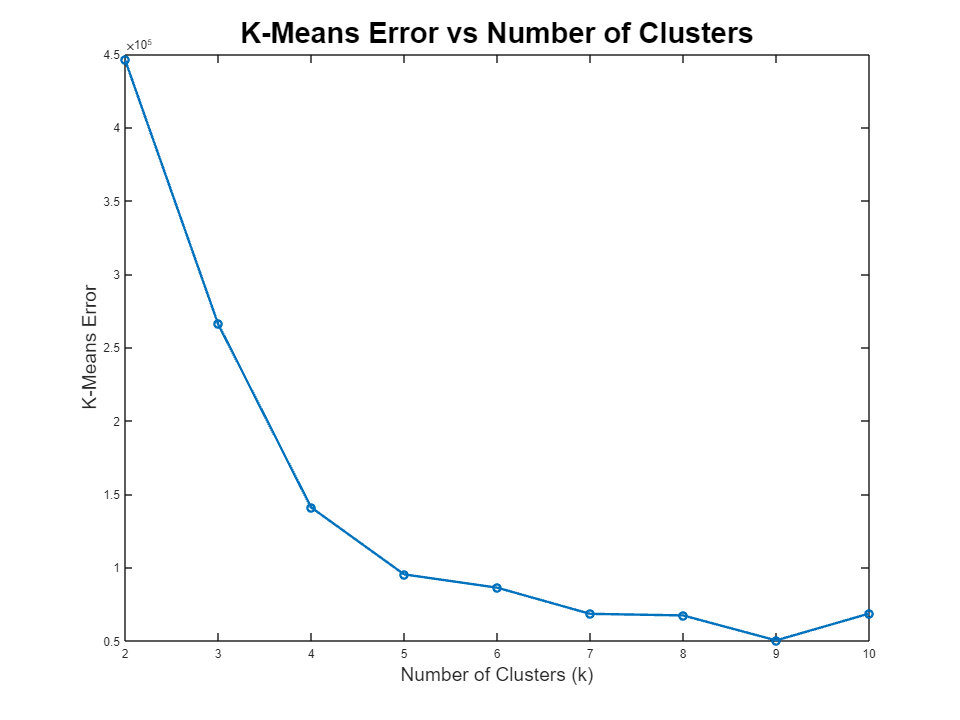


% Plot the results
plot(k_values, errors, '-o', 'LineWidth', 2);

% Configure plot
xlabel('Number of Clusters (k)', FontSize=16);
ylabel('K-Means Error', FontSize=16);
title('K-Means Error vs Number of Clusters', FontSize=24);
saveas(gcf,strcat('Figures/kmeans_errors_italy.png') )

### Hierarchical limiting distance threshold on startend

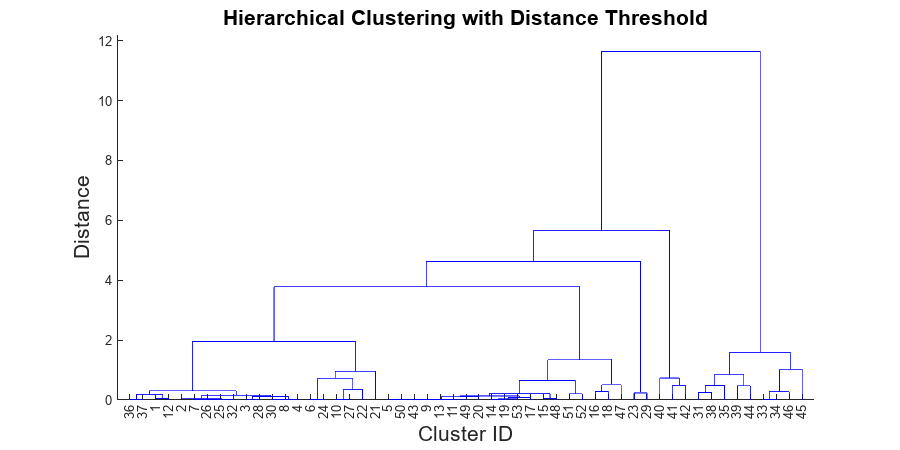

% Perform hierarchical clustering with distance threshold
D = pdist(italy_startend,"euclidean");
Z = linkage(D,'ward');

% Plot dendrogram
dendrogram(Z,53)

% Configure plot
title('Hierarchical Clustering with Distance Threshold', FontSize=16);
xlabel('Cluster ID', FontSize=16);
ylabel('Distance', FontSize=16);
set(gcf, 'Position', [0 0 900 450])
saveas(gcf,strcat('Figures/hier_dendrogram_small_clusters_italy.png') )

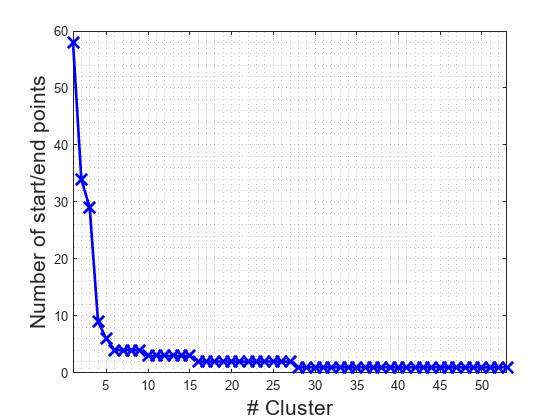

% Get very close start/end points to form clusters where elements are less
% than 1km away
T = cluster(Z,"cutoff", km2deg(1), 'criterion', 'distance');

% Count the number of points in each cluster
counts = histcounts(T,max(T));

% Sort clusters by the number of points
[counts, idx] = sort(counts, 'descend');

figure
plot(counts,'-x', color='b', Linewidth=2, Markersize=12)
grid("minor")
xlabel('# Cluster', FontSize=16)
ylabel('Number of start/end points', FontSize=16)
xlim([1,max(T)])
saveas(gcf,strcat('Figures/hier_small_clusters_italy.png') )


% Get the 3 clusters with the most appearances
top_clusters = idx(1:3)

top_clusters =      6     2     8



% Plot
colors = hsv(size(top_clusters,2)); % Default Matlab color map
geoscatter(italy_startend(T==idx(1),1),italy_startend(T==idx(1),2),'filled','MarkerFaceColor',1-colors(1,:)*0.3)
mean(italy_startend(T==idx(1),:),1)

ans =    45.8496    9.3974


hold on
geoscatter(mean(italy_startend(T==idx(1),1)),mean(italy_startend(T==idx(1),2)),'filled','MarkerFaceColor',1-colors(1,:),'MarkerEdgeColor','k')
for jj = 2:size(top_clusters,2)
    geoscatter(italy_startend(T==idx(jj),1),italy_startend(T==idx(jj),2),'filled','MarkerFaceColor',1-colors(jj,:)*0.3)
    geoscatter(mean(italy_startend(T==idx(jj),1)),mean(italy_startend(T==idx(jj),2)),'filled','MarkerFaceColor',1-colors(jj,:),'MarkerEdgeColor','k')
    mean(italy_startend(T==idx(jj),:),1)
end

ans =    45.8507    9.3962


ans =    45.4994    9.1515


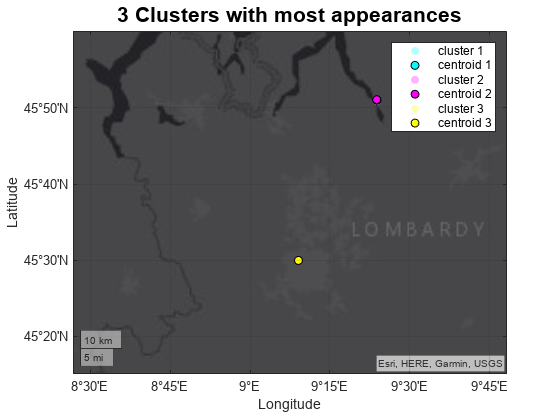

hold off
geobasemap('streets-dark')
legend('cluster 1', 'centroid 1','cluster 2', 'centroid 2','cluster 3', 'centroid 3')
geolimits([45.25,46],[8.75,9.5])
title('3 Clusters with most appearances', FontSize=16);
saveas(gcf,strcat('Figures/possible_home_locations_1.png') )


% Get the 2 clusters with the most appearances
top_clusters = idx(1:2)

top_clusters =      6     2



% Plot
% colors = hsv(size(top_clusters,2)); % Default Matlab color map
geoscatter(italy_startend(T==idx(1),1),italy_startend(T==idx(1),2),'filled','MarkerFaceColor',1-colors(1,:)*0.3)
hold on
mean(italy_startend(T==idx(1),:),1)

ans =    45.8496    9.3974



geoscatter(mean(italy_startend(T==idx(1),1)),mean(italy_startend(T==idx(1),2)),'filled','MarkerFaceColor',1-colors(1,:),'MarkerEdgeColor','k')
for jj = 2:size(top_clusters,2)
    geoscatter(italy_startend(T==idx(jj),1),italy_startend(T==idx(jj),2),'filled','MarkerFaceColor',1-colors(jj,:)*0.3)
    geoscatter(mean(italy_startend(T==idx(jj),1)),mean(italy_startend(T==idx(jj),2)),'filled','MarkerFaceColor',1-colors(jj,:),'MarkerEdgeColor','k')
    mean(italy_startend(T==idx(jj),:),1)
end

ans =    45.8507    9.3962


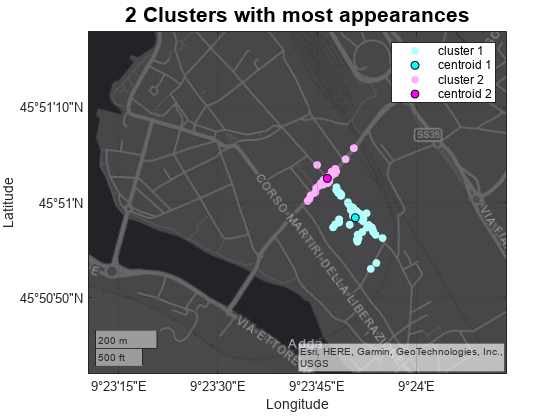

hold off
geobasemap('streets-dark')
legend('cluster 1', 'centroid 1','cluster 2', 'centroid 2')
geolimits([45.845,45.855],[9.39,9.40])
title('2 Clusters with most appearances', FontSize=16);
saveas(gcf,strcat('Figures/possible_home_locations_2.png') )


top_clusters = idx(3)

top_clusters = 8

% Plot
% colors = hsv(size(top_clusters,2)); % Default Matlab color map
hold on
geoscatter(italy_startend(T==top_clusters,1),italy_startend(T==top_clusters,2),'filled','MarkerFaceColor',1-colors(3,:)*0.3)
mean(italy_startend(T==top_clusters,:),1)

ans =    45.4994    9.1515


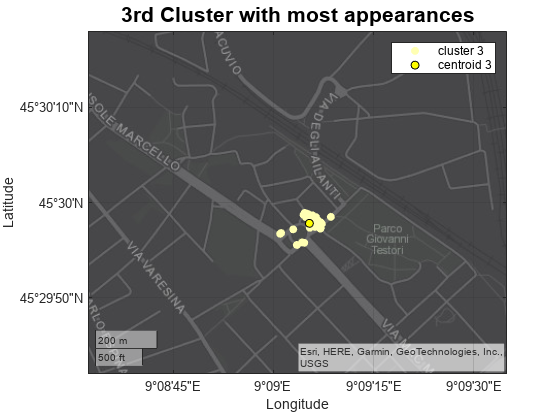

geoscatter(mean(italy_startend(T==top_clusters,1)),mean(italy_startend(T==top_clusters,2)),'filled','MarkerFaceColor',1-colors(3,:),'MarkerEdgeColor','k')
hold off
geobasemap('streets-dark')
legend('', '','', '','cluster 3', 'centroid 3')
geolimits([45.495, 45.505],[9.146,9.156])
title('3rd Cluster with most appearances', FontSize=16);
saveas(gcf,strcat('Figures/possible_home_locations_3.png') )

## Save data to plot with format in python/leaflet maps

home_clusters = table(T, italy_startend(:,1), italy_startend(:,2), 'VariableNames', {'Cluster_ID', 'Latitude', 'Longitude'});
writetable(home_clusters, strcat(data_path,'home_locations.csv'));

## Aux Functions

function d = great_circle_distance(p1, p2)
    % Cast input arguments to single or double
    lat1 = single(p1(1));
    lon1 = single(p1(2));
    lat2 = single(p2(1));
    lon2 = single(p2(2));
    
    % Convert latitude and longitude to radians
    lat1 = deg2rad(lat1);
    lon1 = deg2rad(lon1);
    lat2 = deg2rad(lat2);
    lon2 = deg2rad(lon2);
    
    % Earth's radius in km
    R = 6371;
    
    % Compute Great Circle distance
    d = acos(sin(lat1) * sin(lat2) + cos(lat1) * cos(lat2) * cos(lon1 - lon2)) * R;
end
